# 仿真数据后处理

## 读取数据

clear;
clc;

#### 根据压强计算摩擦因子

rho=1065;
Um=1;
L=1;
d=0.008;
mu=0.004;
nu=3.75e-6;
Re=Um*d/nu;
%lambda=(data(365,12)-data(820,12))/(0.5*Um^2*L/d);
lambda1=64/Re;
lambda2=0.3164/(Re^(0.25));

#### 剖面数据

Path1="C:\Users\admin\Desktop\normal\ds0.01_200_SA_Re2130";
ds=0.01;
Nz=200;
wdstart=floor(0.8/(2.2/Nz));
wdend=floor(1.8/(2.2/Nz));
[data,head,all]=xlsread(strcat(Path1,"\slice.csv"));
ynum=length(data(:,1))/Nz;
ws=mean(data(wdstart:wdend,17));%壁面切应力

for i=1:ynum/2
    uba(i)=mean(data(wdstart+(i-1)*Nz:wdend+(i-1)*Nz,8));
    y(i)=data(i*Nz-1,2);
end
uTao=sqrt(ws);
figure
yplus=uTao*(y(:)+0.004)/nu;
uplus=uba(:)/uTao;
semilogx(yplus,uplus,'-b','LineWidth',2);hold on;
yplus1=0:0.1:25;
uplus1=yplus1

uplus1 =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


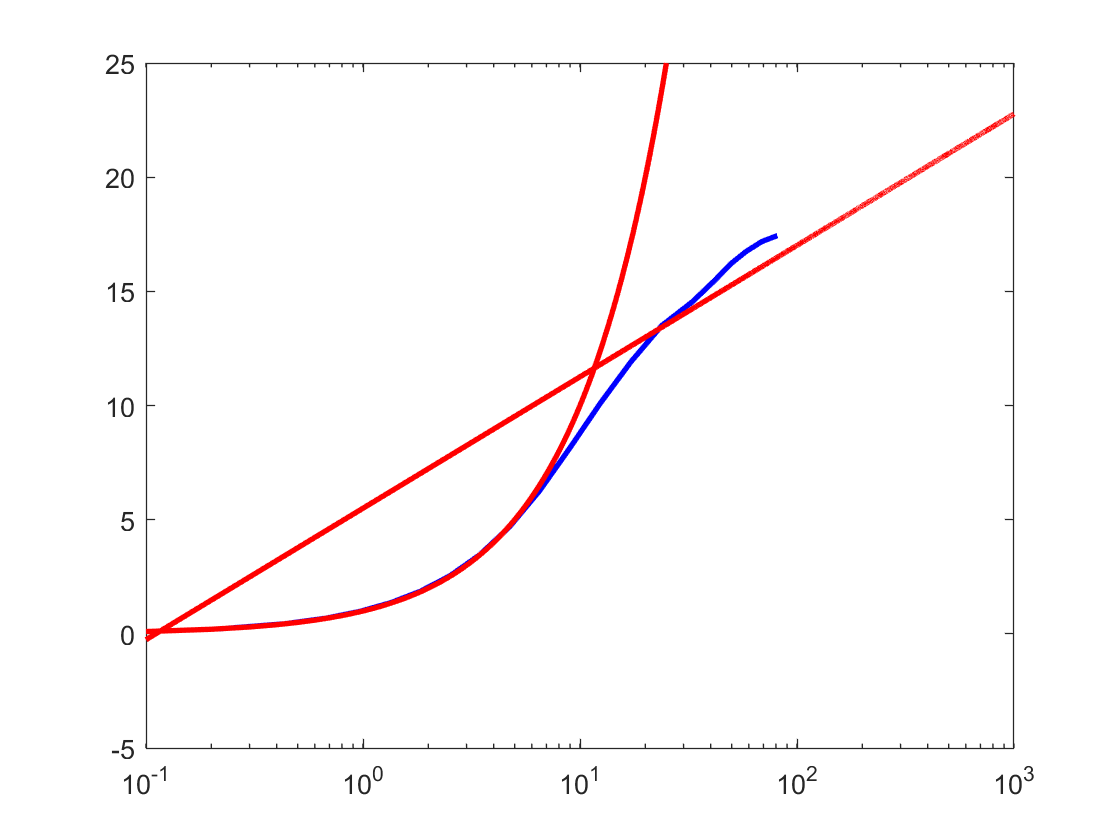

yplus2=0:0.1:1000;
uplus2=(2.5.*log(yplus2)+5.5);
semilogx(yplus1,uplus1,'-r','LineWidth',2);hold on;
semilogx(yplus2,uplus2,'-r','LineWidth',2);

for i=1:ynum
    pbastart(i)=data(wdstart+(i-1)*Nz,11);
    pbaend(i)=data(wdend+(i-1)*Nz,11);
end
lambda=(mean(pbastart)-mean(pbaend))/(0.5*Um^2*L/d);
% figure
% plot(xyz(:,2),UMag,'-b','LineWidth',2);hold on;
% plot(xyz1(:,2),UMag1,'-r','LineWidth',2);
% % ti=title("Velocity Profile");
% % ti.FontSize=18;
% lg=legend("z=2.1","z=0.001");
% lg.FontSize=18;
% xlabel('$y$[m]','interpreter','latex', 'FontSize', 18);
% ylabel('$U$[m/s]','interpreter','latex', 'FontSize', 18);
% 
% [data,head,all]=xlsread(strcat(Path1,"\y=-0.004.csv"));
% 
% figure
% plot(data(20:end-20,3),data(20:end-20,16),'-b','LineWidth',2);hold on;
% lg=legend("wallshear");
% lg.FontSize=18;
% xlabel('$z$[m]','interpreter','latex', 'FontSize', 18);
% ylabel('wallshear[Pa]', 'FontSize', 18);
% 
% % figure
% % yplus=uTao*(xyz(:,2)+0.004)/nu;
% % uplus=Uxyz(:,2)/uTao;
% % Ret=rho*uTao*d/mu;
% % plot(yplus,uplus);
% 
% 
% 

#### 压强数据%OpenFoam是单位密度的压强，Fluent是实际压强

% [data,head,all]=xlsread(strcat(Path1,"\xy=0.csv"));
% figure
% plot(data(2:end,3),data(2:end,12),'-b','LineWidth',2);
% lg=legend("P");
% lg.FontSize=18;
% xlabel('$z$[m]','interpreter','latex', 'FontSize', 18);
% ylabel('$P$[Pa]','interpreter','latex', 'FontSize', 18);

## 输出数据

head1=["网格第一层尺寸","网格轴向尺寸","雷诺数","仿真计算的摩擦系数","层流公式计算摩擦系数","湍流公式计算摩擦系数"];
basic=[ds,2.2/(Nz-1),Re,lambda,lambda1,lambda2];
shuchu=[yplus,uplus];
shuchu1=[yplus1',uplus1'];
shuchu2=[yplus2',uplus2'];
xlswrite(strcat(Path1,'\Data.xlsx'),shuchu,1,"A1");
xlswrite(strcat(Path1,'\Data.xlsx'),shuchu1,2,"A1");
xlswrite(strcat(Path1,'\Data.xlsx'),shuchu2,3,"A1");
xlswrite(strcat(Path1,'\Data.xlsx'),head1,4,"A1");
xlswrite(strcat(Path1,'\Data.xlsx'),basic,4,"A2");
